# Example: KUKA Agilus KR6

This example shows how PSDM can be used to derive the regressor for of the dynamics of motion of a 6-DOF spherical-wrist manipulator.

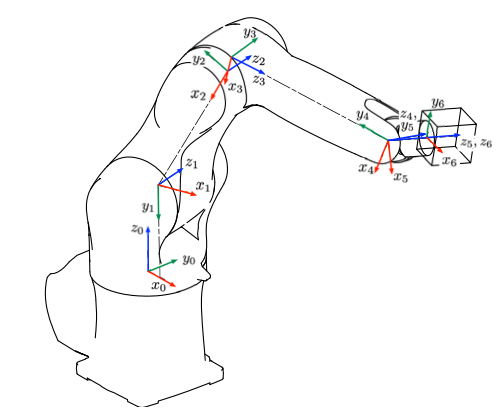

## Derivation

First, we define the DH table of the maniuplator. For the input to this toolbox, DH table must be defined as a $n\times 6%$ double matrix:


$$\text{DH} = \left[\matrix{
a_1 & \alpha_1 & d_1 & \theta_1 & t_1 & s_1 \cr
\vdots &\vdots &\vdots &\vdots &\vdots &\vdots \cr
a_n & \alpha_n & d_n & \theta_n & t_n & s_n \cr
 }\right]$$


where $a_i, \alpha_i, d_i$ and $\theta_i$ are the normal DH parameters, $t_i$ indicates the joint type (0 for revolute, 1 for prismatic) and $s_i$ is either a 1 or a -1, and indicates the direction of the joint. Internally, they are combined to make the DH table:


$$\left|
\matrix{
\text{Link Length } a_i & \text{Link twist } \alpha_i & \text{Link offset} d_i & \text{Joint angle } \theta_i \cr
a_i & \alpha_i & d_i + t_i s_i q_i & \theta_i + (1-t_i)s_i q_i
}
\right|$$


d1 = 183e-3;
d4 = 365e-3;
d6 = 80e-3;
a1 = 25e-3;
a2 = -315e-3;
a3 = -35e-3;
DH =   [a1,       -pi/2,   d1,     0,      0,      1;
        a2,       0,       0,      0,      0,      1;
        a3,       pi/2,    0,      0,      0,      1;
        0,        -pi/2,   d4,     0,      0,      1;
        0,        pi/2,    0,      0,      0,      1;
        0,        0,       d6,     0,      0,      1];

We also need a gravity vector. This is a unit vector and is scaled by the gravitational constant internally. Here, gravity is pointing in the negative y direction.

g = [0; 0; 1];

Finally, we (optionally) need to define a vector of inertial parameters of the robot, $X$. This is **not** needed to run the derivation. But, it can be used to specify certain parameters as being zero. Internally, any parameter which is identically zero in the given $X$ matrix is assumed negligible and is not included in the derivation, leading to simpler results.

$X$ is defined as the concatenation of all the inertial parameters:


$$X = \left[
\matrix{
m_1 & r_{x,1} & r_{y,1} & r_{z,1} & I_{xx,1}& I_{yy,1}& I_{zz,1}& I_{xy,1}& I_{xz,1}& I_{yz,1} \cr
\vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots & \vdots \cr
m_n & r_{x,n} & r_{y,n} & r_{z,n} & I_{xx,n}& I_{yy,n}& I_{zz,n}& I_{xy,n}& I_{xz,n}& I_{yz,n}
}
\right]$$


Here, we we make no assumptions about any of the parameters, so we can either set X to be a $n\times 10$ matrix of ones, or just give leave it empty.

Now, we can run the derivation. Because this is a more complex robot, this could take 5-10 minutes to run, depending on the speed of your computer. The derivation time is **much** faster if the PSDM toolbox is "made" first (compiled into C). In this case, the derivation time should be 10-20 seconds. See readme file for details on this.

[E, P] = PSDM.deriveModel(DH, g);


Running gravity derivation (729 search terms).
		729 terms reduced to 74, Took 0.18 seconds.
		Max Reprojection Error: 5.68e-14.
		Reduced from (74 / 74) to 10 parameters (took 1.67 seconds).
		Reprojection error is 3.02e-14
	Gravity matching done. 10 terms remaining (took 1.91 sec total).


Running accel derivation (7448 search terms).

	Searching in joint 1 (3125 terms)...
		3125 terms reduced to 523, Took 1.55 seconds.
		Max Reprojection Error: 2.66e-14.


E is the exponent matrix which represents the terms of the final result. These matrices can be inspected in matlab, however they are a bit large to intuite visually.

## Testing

The PSDM model, defined by E and P, can be used either through full knowledge of $X$, the inertial parameters, or through experimental determination of the $\Theta$ regression parameters.

Here, since we do not have experimental data, we can just use the $X$ parameters above to validate the result. Note, this validation has actually already been performed in the derivation above – this is just to illustrate.

First, use the X2Theta function to convert the X matrix into the appropriate regression vector. We assume some arbitrary list of inertial parameters, simulated by a rand function.

DOF = size(DH, 1);
% Load some typical inertial parameters
X = [7.6 -0.0376 0.0435 -0.0076 0.043 0.0449 0.049 0.0125 0.0022 -0.0024;2.8 0.1554 -0.0062 0.1148 0.006 0.0393 0.0415 -0.0004 -0.0012 0.0001;7 0.045 -0.007 0.004 0.0278 0.0375 0.0309 0.001 0.0005 -0.0002;2.9 -0.001 0.1021 -0.0028 0.0138 0.0058 0.0123 -0.001 0.0002 0.0002;0.94 0.0001 -0.03 0.0106 0.0009 0.001 0.0006 0.0001 0.001 0.0001;3 -0.002 -0.019 0.067 0.0045 0.005 0.006 0.0001 -0.0003 0.0004];
% Get Theta vector numerically from model and X parameters.
Theta = PSDM.X2Theta(E, P, DH, g, X, 5000);

Now, define some random poses.

N = 5;

Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5);
Qdd = (rand(DOF, N)-0.5);

We can use the newton-euler algorithm to get the inverse dynamics.

tau_rne = PSDM.inverseDynamicsNewton(DH, X, Q, Qd, Qdd, 2, g)

tau_rne =       0.40964     -0.23774     -0.91384      0.19246    -0.016288
      -57.676       -26.76      -51.138      -38.636      -25.987
       -19.56         14.3      -21.627        4.748      -2.5553
        1.566      0.59626       4.0327     -0.28861     -0.31999
       -2.862       1.0815      0.05185       1.3553       4.2261
     -0.23856      0.19255      0.33828      0.17102      0.52365


Then use the PSDM model, and check the error:

tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd)

tau_psdm =       0.40964     -0.23774     -0.91384      0.19246    -0.016288
      -57.676       -26.76      -51.138      -38.636      -25.987
       -19.56         14.3      -21.627        4.748      -2.5553
        1.566      0.59626       4.0327     -0.28861     -0.31999
       -2.862       1.0815      0.05185       1.3553       4.2261
     -0.23856      0.19255      0.33828      0.17102      0.52365


fprintf('Max inverse dynamics error: %.5g\n', max(abs(tau_rne(:) - tau_psdm(:))) );

Max inverse dynamics error: 7.383e-14


We can also validate the forward dynamic model by ensuring that we get the same joint accelerations we started with.

Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm)

Qdd_psdm =       0.11017     -0.30734     -0.27477      0.25707      0.10449
     -0.21199     0.081451      0.23574     -0.40173     -0.25859
     -0.22105      0.14928     -0.15214      0.25854     -0.43989
     -0.29145      0.24114     -0.20376    0.0029257    -0.075306
      0.11906      0.24068      0.29538      0.35772     -0.19104
    -0.015329     0.082707      0.26643     -0.36442     -0.43752


fprintf('Max forward dynamics error: %.5g\n', max(abs(Qdd_psdm(:) - Qdd(:))) );

Max forward dynamics error: 5.5317e-14


The errors should be negligible (machine precision levels).

## Faster real time code

The default PSDM functions for inverse and forward dynamics are a bit slow since there is some pre-processing to be done at each step, and complex indexing which is slow for matlab.

However, because the model is quite nicely organized in E and P, we can procedurally create matlab functions which are much faster than the default functions, specifically for a given $\{E, P, \Theta\}$ tuple.

Add the temp directory and define some filenames for the functions:

addpath(fullfile(utilities.PSDMDir, 'temp'));
filename_inverse = fullfile( utilities.PSDMDir, 'temp', 'PSDM_inverseDynamics_agilus.c');
filename_forward = fullfile( utilities.PSDMDir, 'temp', 'PSDM_forwardDynamics_agilus.c');

Can decide if you want to mex-compile your code or not. To use the mex feature, you will need to have a compiler installed on your machine. Setting this to true also requires you to have access to the "Matlab Coder", and, if possible, the Parallel Computing Toolbox. If you have the latter installed, navigate to the function "+PSDM/config.m" and set the parameter "use_par" to "true".

doMex = true; % Whether or not to mex result for speed

Now, derive functions

PSDM.makeInverseDynamics(filename_inverse, E, P, 'mex', doMex);

Compiling into mex file...
Building with 'Xcode with Clang'.
MEX completed successfully.
Done!


PSDM.makeForwardDynamics(filename_forward, E, P, 'mex', doMex);

Compiling into mex file...
Building with 'Xcode with Clang'.
MEX completed successfully.
Done!


C-code has now been generated in the directory /temp. If doMex was set to true, then you will also have access to the generated MEX files.

## Test Evaluation Speed

The code below generations a large number of sample poses and checks the evaluation speed of the forward and inverse dynamics functions. This code will only work if you have mexed the files above.

% Generate samples
N = 1e4;
Q = (rand(DOF, N)-0.5) * (2*pi);
Qd = (rand(DOF, N)-0.5) * (10);
Qdd = (rand(DOF, N)-0.5) * (50);

% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
tic1 = tic;
tau_psdm = PSDM.inverseDynamics(E, P, Theta, Q, Qd, Qdd);
t1 = toc(tic1);

fprintf("Default inverse dynamics function took %.3g seconds per state.\n", t1/N);

Default inverse dynamics function took 0.000213 seconds per state.



A = PSDM_inverseDynamics_agilus(Q(:, 1), Qd(:, 1), Qdd(:, 1), Theta);
tic2 = tic;
tau_psdm_opt = PSDM_inverseDynamics_agilus(Q, Qd, Qdd, Theta);
t2 = toc(tic2);

fprintf("Optimized inverse dynamics function took %.3g seconds per state.\n", t2/N);

Optimized inverse dynamics function took 2.78e-06 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(tau_psdm(:) - tau_psdm_opt(:))) );

Maximum error: 1.0057e-10



tic3 = tic;
Qdd_psdm = PSDM.forwardDynamics(E, P, Theta, Q, Qd, tau_psdm);
t3 = toc(tic3);

fprintf("Default forward dynamics function took %.3g seconds per state.\n", t3/N);

Default forward dynamics function took 0.000253 seconds per state.



% Run test. We run the function once first since matlab doesn't run
% functions very quickly the first time.
A = PSDM_forwardDynamics_agilus(Q(:, 1), Qd(:, 1), tau_psdm(:, 1), Theta);
tic4 = tic;
Qdd_psdm_opt = PSDM_forwardDynamics_agilus(Q, Qd, tau_psdm, Theta);
t4 = toc(tic4);

fprintf("Optimized forward dynamics function took %.3g seconds per state.\n", t4/N);

Optimized forward dynamics function took 2.6e-06 seconds per state.



fprintf("Maximum error: %.5g\n", max(abs(Qdd_psdm(:) - Qdd_psdm_opt(:))) );

Maximum error: 1.1156e-09
